dataFolder = '/GEE_30m';
labelIDs = [0 1];
pixelLabelIDs = {0 1};
classes = ["no_label", "flood"];
imgDir = fullfile(pwd, dataFolder, '/train', 'images');

imds = imageDatastore(imgDir)

imds =   ImageDatastore with properties:

                       Files: {
                              'C:\Do-an\GEE_30m\train\images\s1_flooded_20201010.tif';
                              'C:\Do-an\GEE_30m\train\images\s1_flooded_20201017.tif';
                              'C:\Do-an\GEE_30m\train\images\s1_flooded_20201023.tif'
                              }
                     Folders: {
                              'C:\Do-an\GEE_30m\train\images'
                              }
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                      Labels: {}
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


labelDir = fullfile(pwd, dataFolder, '/train', 'labels');
pxds = pixelLabelDatastore(labelDir, classes, pixelLabelIDs)

pxds =   PixelLabelDatastore with properties:

                       Files: {3×1 cell}
                  ClassNames: {2×1 cell}
                    ReadSize: 1
                     ReadFcn: @readDatastoreImage
    AlternateFileSystemRoots: {}


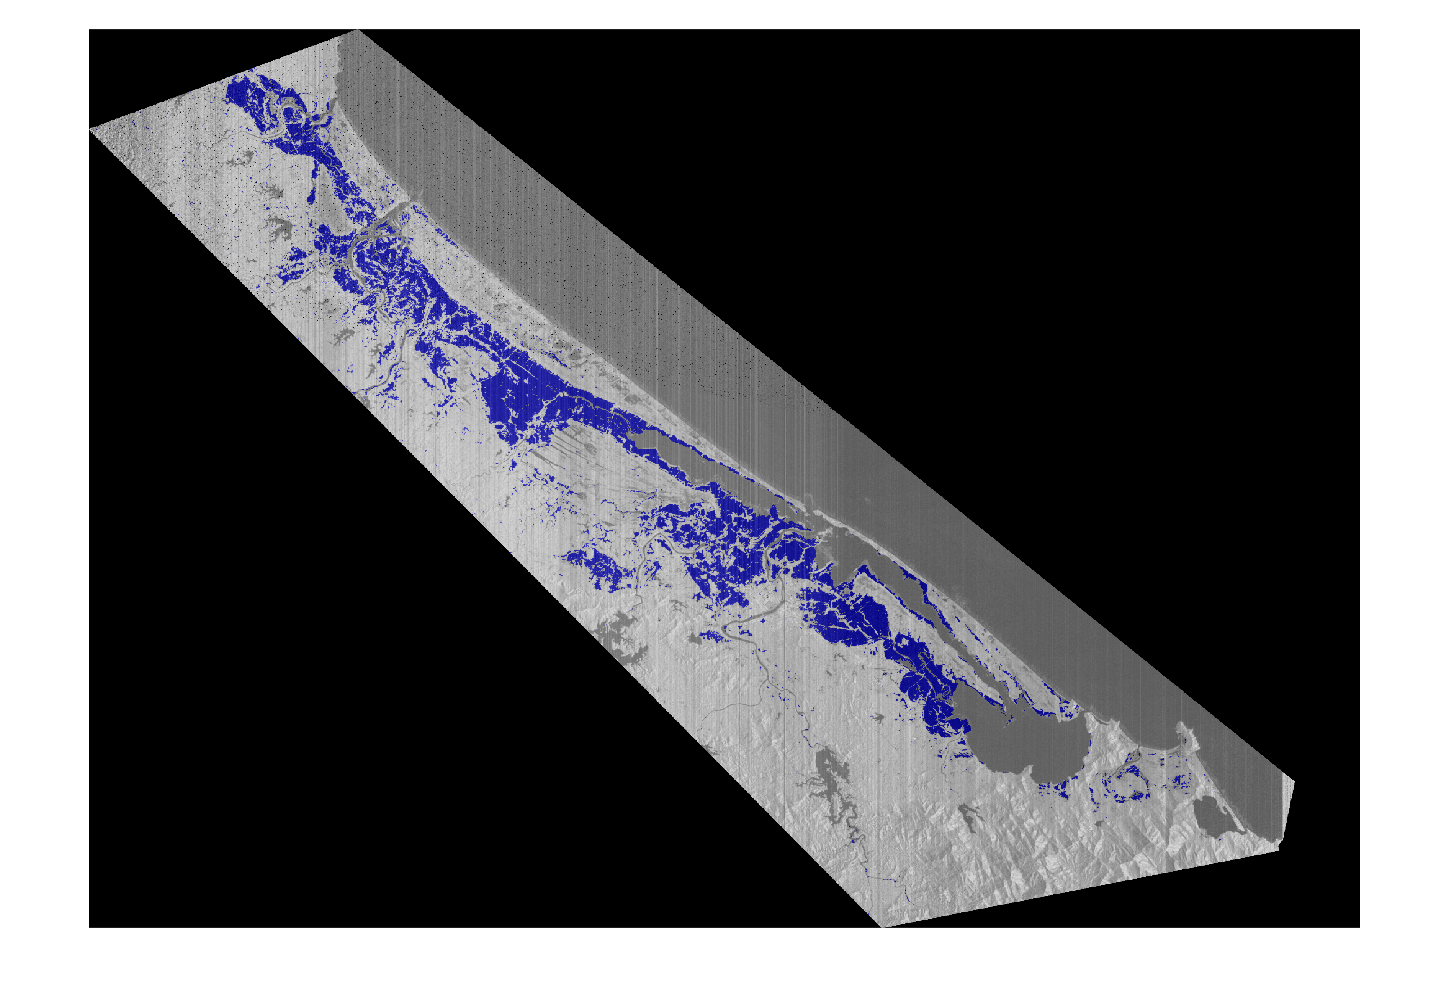

i = readimage(imds, 1);
c = readimage(pxds, 1);
i1 = normalize(i, 'range', [0 1]);
c1 = double(c);
b = labeloverlay(i1,c1,'ColorMap', [0.7 0.7 0.7; 0 0 1]);
imshow(b);

tbl = countEachLabel(pxds)

tbl = 2×3 table
        Name        PixelCount    ImagePixelCount
    ____________    __________    _______________

    {'no_label'}    5.3147e+07      5.4805e+07   
    {'flood'   }    1.6583e+06      5.4805e+07   


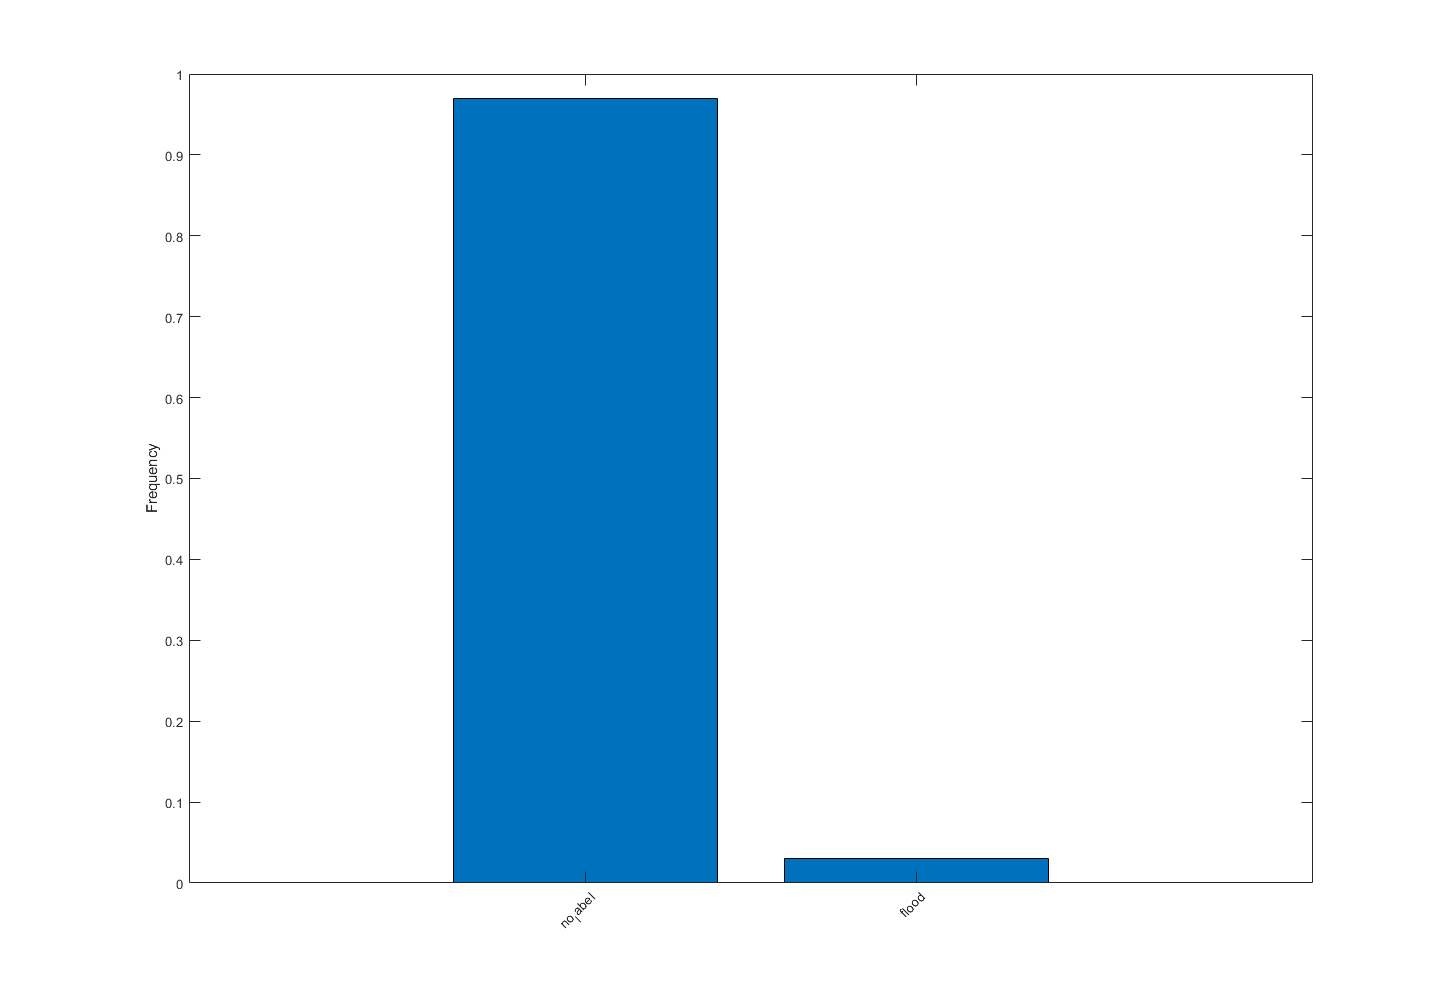

frequency = tbl.PixelCount/sum(tbl.PixelCount);

bar(1:numel(classes),frequency)
xticks(1:numel(classes)) 
xticklabels(tbl.Name)
xtickangle(45)
ylabel('Frequency')

imageFreq = tbl.PixelCount ./ tbl.ImagePixelCount;
classWeights = median(imageFreq) ./ imageFreq

classWeights =     0.5156
   16.5241


inputTileSize = [256, 256, 1];
patchesPerImage = 400;
dsTrain = imbalanceRandomPatchExtractionDatastore(imds, pxds, inputTileSize(1:2), 0.2, 1000, "PatchesPerImage", patchesPerImage);
inputBatch = preview(dsTrain);
disp(inputBatch)

       InputImage       ResponsePixelLabelImage
    ________________    _______________________

    {256×256 double}     {256×256 categorical} 
    {256×256 double}     {256×256 categorical} 
    {256×256 double}     {256×256 categorical} 
    {256×256 double}     {256×256 categorical} 
    {256×256 double}     {256×256 categorical} 
    {256×256 double}     {256×256 categorical} 
    {256×256 double}     {256×256 categorical} 
    {256×256 double}     {256×256 categorical} 



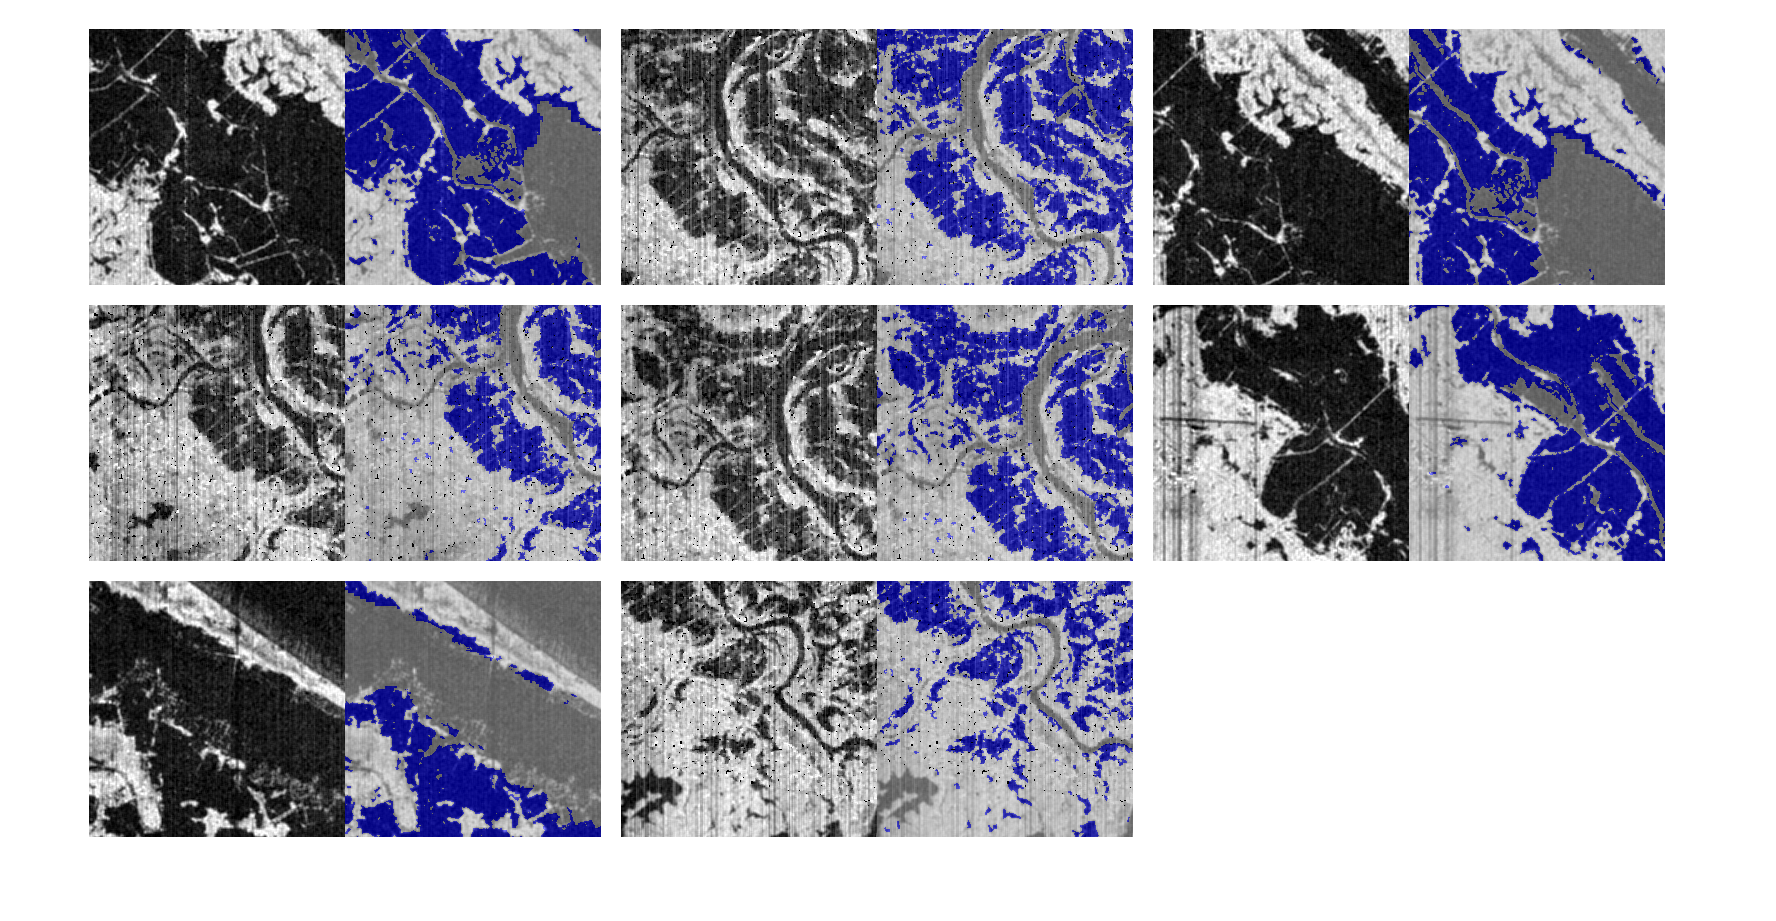

showImageWithLabel(inputBatch)

valImgDir = fullfile(pwd, dataFolder, '/validate', 'images');
valImds = imageDatastore(valImgDir)

valImds =   ImageDatastore with properties:

                       Files: {
                              'C:\Do-an\GEE_30m\validate\images\s1_flooded_20201109.tif'
                              }
                     Folders: {
                              'C:\Do-an\GEE_30m\validate\images'
                              }
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                      Labels: {}
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


valLabelDir = fullfile(pwd, dataFolder, '/validate', 'labels');
valPxds = pixelLabelDatastore(valLabelDir, classes, pixelLabelIDs)

valPxds =   PixelLabelDatastore with properties:

                       Files: {'C:\Do-an\GEE_30m\validate\labels\flooded_20201109.tif'}
                  ClassNames: {2×1 cell}
                    ReadSize: 1
                     ReadFcn: @readDatastoreImage
    AlternateFileSystemRoots: {}


dsValidate = imbalanceRandomPatchExtractionDatastore(imds, pxds, inputTileSize(1:2), 0.05, 1000, "PatchesPerImage", patchesPerImage);

% pxLayer = dicePixelClassificationLayer('Name','dice-Pixel-Classification-Layer','Classes',tbl.Name);
% pxLayer = pixelClassificationLayer('Name','Pixel-Classification-Layer','Classes',tbl.Name,'ClassWeights',classWeights);
% lgraph = createUnet(inputTileSize, numel(classes), pxLayer);
lgraph = unetLayers(inputTileSize, numel(classes), "EncoderDepth", 4, "FilterSize",3);

Unrecognized function or variable 'numelclasses'.

disp(lgraph.Layers)

initialLearningRate = 0.1;
maxEpochs = 200;
minibatchSize = 8;
l2reg = 0.0001;

options = trainingOptions('sgdm',...
    'InitialLearnRate',initialLearningRate,...
    'ValidationData', dsValidate,...
    'Momentum',0.9,...
    'L2Regularization',l2reg,...
    'MaxEpochs',maxEpochs,...
    'MiniBatchSize',minibatchSize,...
    'LearnRateSchedule','piecewise',...
    'LearnRateDropFactor', 0.15,...
    'LearnRateDropPeriod', 1000,...
    'Shuffle','every-epoch',...
    'GradientThresholdMethod','l2norm',...
    'GradientThreshold',0.05,...
    'Plots','training-progress',...
    'VerboseFrequency',20,...
    "ExecutionEnvironment","gpu",...
    "CheckpointPath", strcat(pwd, dataFolder, '/checkpoint'));

doTraining = true;
if doTraining
    modelDateTime = datestr(now,'dd-mmm-yyyy-HH-MM-SS');
    [net,info] = trainNetwork(dsTrain,lgraph,options);
    save(['savedUnet-' modelDateTime '-Epoch-' num2str(maxEpochs) '.mat'],'net','options');
end